% File: main.m

clear;
clc;
close all;

% Chebyshev linkage: a = 207.5
MAX = 97;
MIN = 37;
input = deg2rad(linspace(MAX, MIN, 30));

a = 200;
h = a;
r1 = 4*a; a1 = -pi;
r2 = 5*a; a2 = input(1);
r3 = 2*a; a3 = 0;
r4 = 5*a; a4 = 0;

r16 = 0; a16 = 0;
r6 = 2*a; a6 = 0;
r5 = 1.25001*r6; a5 = 0;
r15 = 0.5*r4; a15 = 0;


v1 = ["r2", "a2"; "r3", "a3"; "r4", "a4"; "r1", "a1"];
c1 = [r2, a2; r3, a3; r4, a4; r1, a1];

v2 = ["r16", "a16"; "r6", "a6"; "r5", "a5"; "r15", "a15"; "r1", "a1"];
c2 = [r16, a16; r6, a6; r5, a5; r15, a15; r1, a1];

s1 = MAE162A.initData(v1, c1, ["a3", "a4"]);
s2 = MAE162A.initData(v2, c2, ["a6", "a5"]);

optimize = true; % use either NewtonRaphson or VPA to solve

[data1, idx1] = MAE162A.simulate1(input, s1, optimize)

data1 = 1×30 struct array with fields:
    r2
    a2
    r3
    a3
    r4
    a4
    r1
    a1
    parameters
    variables


idx1 = 1×30 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0


[data2, idx2] = MAE162A.simulate2(data1, s2, optimize)

data2 = 1×30 struct array with fields:
    r16
    a16
    r6
    a6
    r5
    a5
    r15
    a15
    r1
    a1
    parameters
    variables


idx2 = 1×30 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0


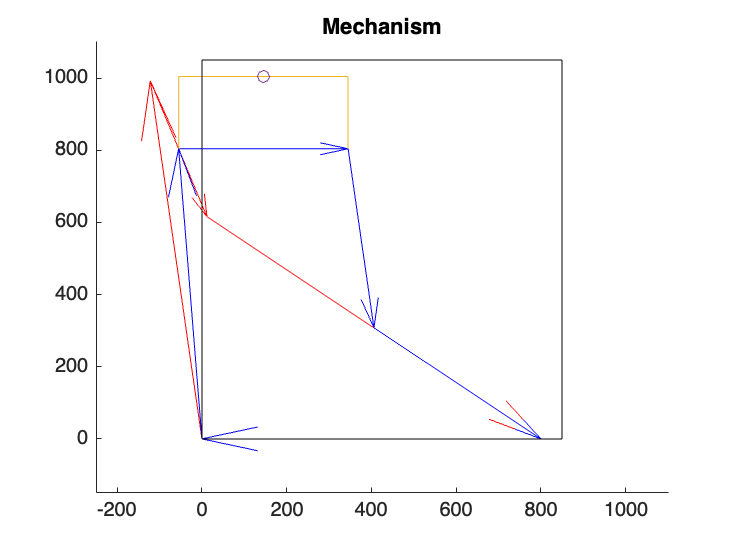


movie = false; % flag to save simulation as a gif and plots as jpgs
photo = false;

extendedData1 = [data1(idx1), flip(data1(idx1))];
extendedData2 = [data2(idx2), flip(data2(idx2))];
scale = [-250 1100 -150 1100];

fig = figure(1);
MAE162A.showSimulation(fig, scale, movie, 'Mechanism', extendedData1, extendedData2)

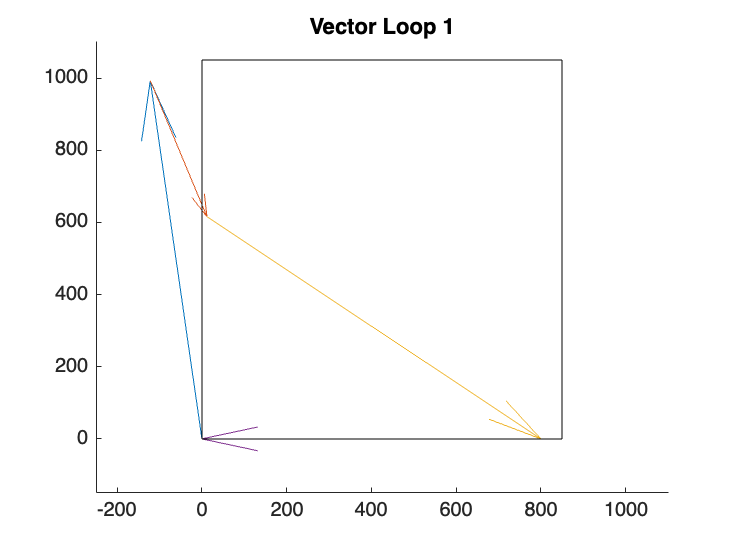


clear fig
fig = figure(1);
MAE162A.showSimulation(fig, scale, movie, 'Vector Loop 1', extendedData1)

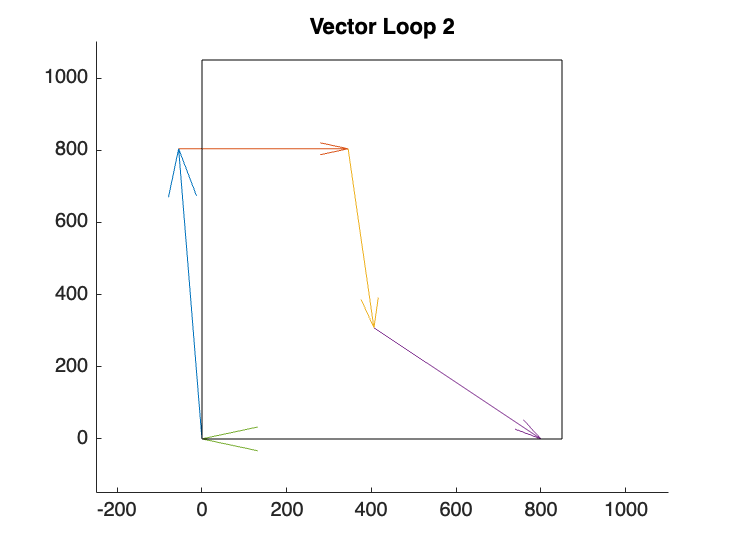


clear fig
fig = figure(1);
MAE162A.showSimulation(fig, scale, movie, 'Vector Loop 2', extendedData2)

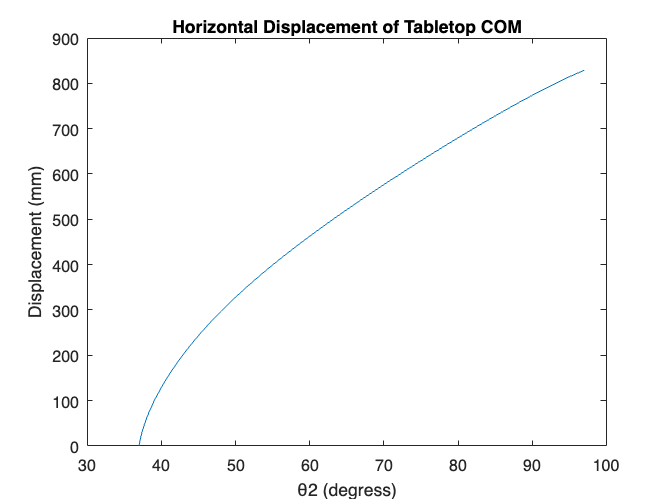

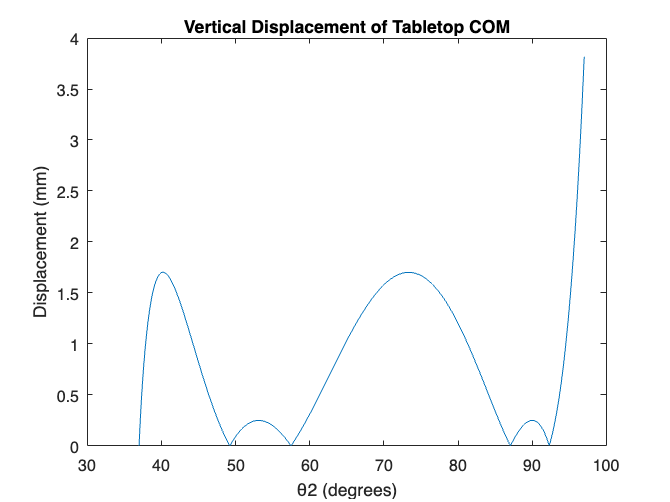


MASS = [2.06117; 2.56540; 1.03841; 2.55108; 1.23193; 1.91537]; % from solidworks
MAE162A.positionAnalysis(a, MAX, MIN, 10, 20, photo)

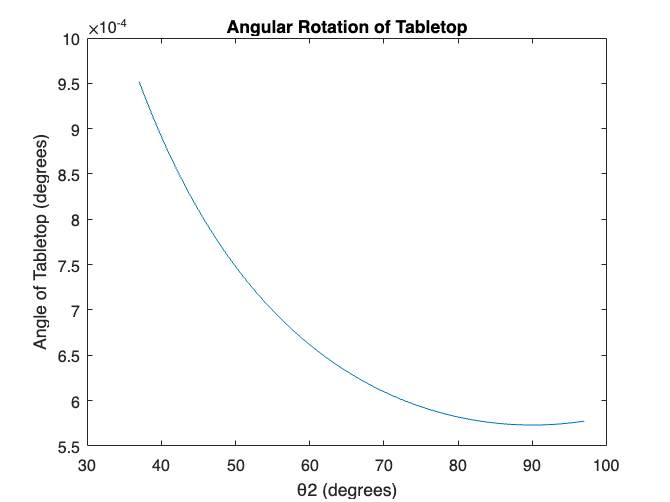

MAE162A.angularAnalysis(a, MAX, MIN, 30, photo)

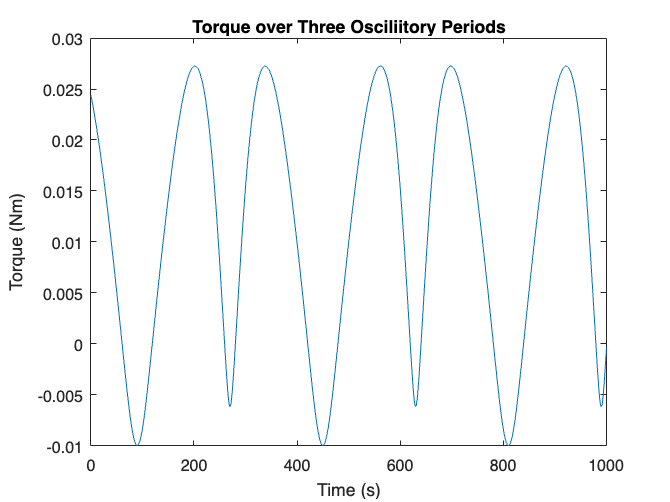

MAE162A.torqueAnalysis(a, MAX, MIN, MASS, 40, photo)